# Introduction to Plotting and Vectorization

This lab will provide an introduction to two dimensional plots. At the end, you should feel comfortable plotting functions of the form f(x). You should find this useful not only for visualizing the solutions of ODEs, but also for plotting general data that might appear in other courses and work.

In the process we will also introduce the concept of vectorization, which is helpful for writing efficient and "clean" code. Vectorization is a concept found not only in MATLAB but also C/C++, Fortran, and other languages.

Opening the m-file lab1.m in the MATLAB editor, step through each part using cell mode to see the results. Compare the output with the PDF, which was generated from this m-file.

There are twelve (12) exercises in this lab that will be graded. Write your solutions in the template, including appropriate descriptions in each step. Save the .m file as lab1_<UTORid>.m and submit it online on Quercus. Also, submit a PDF of the output by generating html (by going to 'File', 'Publish') and then saving to a PDF called lab1_<UTORid>.pdf. Substitute your UTORid for [UTORid](http://utorid).

## Student Information

Student Name: Patricia Nadia Krisanti

Student Number:  1009669404

## Creating Vectors Explicitly

MATLAB plots vectors (also known as arrays) of data points. The first way to create vectors is to give MATLAB a list of values of the form:

x = [value1, value2, value3, ..., valueN];

We can then see the values in the array x by entering `x` without a semilcolon or with the command `disp(x)`, with or without the semicolon.

Individual entries of the vector can be accessed with the command `x(i)`, where `i` is between 1 and the length of the array. If `i` is not in this range an error is thrown.

Examine the following commands and their output.

x = [.5, 1.0, 2.3, 4.0, 4.333, 5.];     %These are arbitrary values
x

x =     0.5000    1.0000    2.3000    4.0000    4.3330    5.0000


disp(x)

    0.5000    1.0000    2.3000    4.0000    4.3330    5.0000



disp(x);

    0.5000    1.0000    2.3000    4.0000    4.3330    5.0000



x(1) 

ans = 0.5000

x(2)

ans = 1

## Exercise 1

Objective: Observe a MATLAB error when you try to access an invalid index.

Details: Try to access elements of the vector `x`, created in the previous step at the command prompt `>>`. Try values of `i` outside the valid range. Try negative values, zero, and large positive values. Copy down the error message in each case, and report this in your submitted work as:

Error for negative index: Array indices must be positive integers or logical values.

Error for zero index: Array indices must be positive integers or logical values.

Error for positive index outside of the bounds: Index exceeds the number of array elements. Index must not exceed 6. (where 6 is the highest bounds)

Only include the error message as a comment (with the percent signs), DO NOT INCLUDE THE CODE IN YOUR SUBMISSION.

## Plotting a Vector

Given a list (one dimensional array) of values we can plot them with the command `plot(x)`, with or without a semicolon. This will plot the points in the data set `(i, x(i))`.

plot(x)

## Plotting Vector x against Vector y

To plot functions, we need two vectors: a set of x points and a corresponding set of y points. We now create a vector `y` and plot x against y with the command `plot(x,y)`.

If the two vectors are not the same size, MATLAB will throw an error.

y = [3.7, -3.4, 1.02, 2.2, .04, 1.0];   %These are arbitrary values
plot(x,y)

## Exercise 2

Objective: Create two vectors and plot one against the other.

Details: Explicitly create the vectors 

x = [-5, -3, -1, 0, 2, 4, 6] 

and 

y = [-25, -9, -1, 0, 4, 16, 36]

And plot `x` against `y`. Your submission should show both the creation of the vectors and the figure, as in the example.

x = [-5, -3, -1, 0, 2, 4, 6] 

x =     -5    -3    -1     0     2     4     6


y = [-25, -9, -1, 0, 4, 16, 36]

y =    -25    -9    -1     0     4    16    36


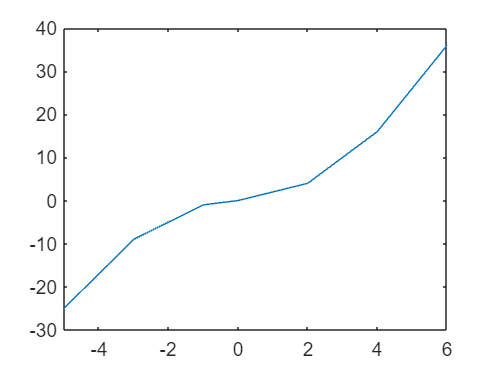

plot(x,y)

## Creating Vectors with For Loops

Entering the values by hand is tedious and error prone. We can use MATLAB's programming features to create them. Suppose we want to create a vector of N points between 0 and 1, equally spaced and inclusive. This would be useful if we wanted to evaluate a function, f(x), at all of these values.

The distance between the points will be h = (1 - 0)/(N-1), so that:

0 = x(1) = 0 * h < x(2) = 1 * h < ... < x(j) = (j-1) * h < ... < x(N) = (N-1) * j = 1

NOTE: if we with to do this between two arbitrary points, a < b, instead of 0 and 1, the values would be: h = (b - a)/(N-1) and a = x(1) = a + 0 * h < x(2) = a+ 1 * h < ... < x(j) = a +(j-1) * h < ...< x(N) = b

We assign a value of N, compute h, preallocate a vector x, and then loop through the vector.

By 'preallocate' we mean 'set aside an array of the appropriate size in memory for future use'. Preallocation can be done with the command `x = zeros(N,1);`, which makes an array of length N in which all the entries are zero. Other options are possible, too.

N = 11;             %Alter this value to see different results
h = (1-0)/(N-1);
x = zeros(N,1);     %This creates a column vector.  
                    %zeros(1,N) would create a row vector.

for j = 1:N
    x(j) = (j-1) * h;
end
disp(x);

         0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000
    1.0000



## Plotting y = x^2

As a first example of plotting a function, we plot y = x^2. Using the array `x` created in the last step, we populate a vector `y` such that `y(i) = x(i)^2` and plot it.

y = zeros(N,1);     %Preallocate the array

for j = 1:N
    y(j) = x(j)^2;
end

disp(y);

         0
    0.0100
    0.0400
    0.0900
    0.1600
    0.2500
    0.3600
    0.4900
    0.6400
    0.8100
    1.0000



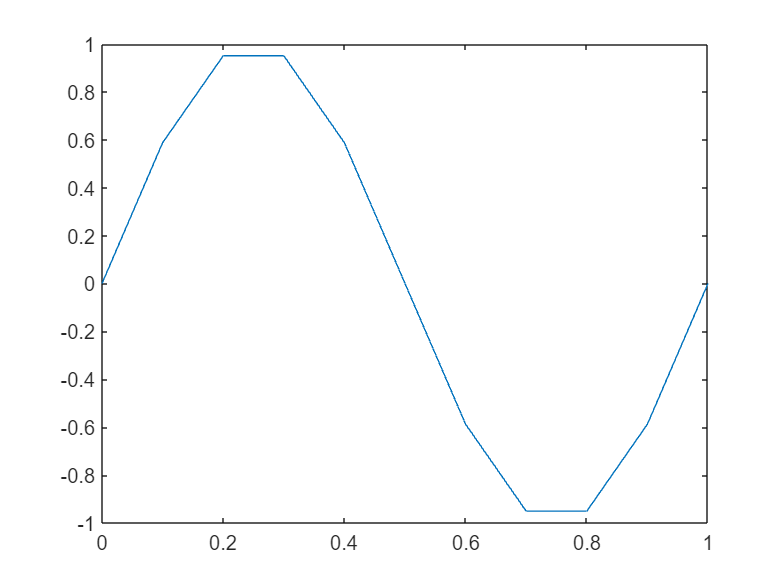


plot(x,y)

## Plotting y = sin(2 * pi * x)

MATLAB has a number of built in functions including the trigonometric functions (sin, cos, arccos,...), the exponential functions (exp), the natural logarithm function (log), hyperbolic functions (sinh, cosh), and others. The constant `pi` is also defined. For a full list of built in functions type `help elfun` at the MATLAB command line. 

We create the vector `z` with `z(j) = sin(2*pi*x(j))`, using the same array as from the previous steps.

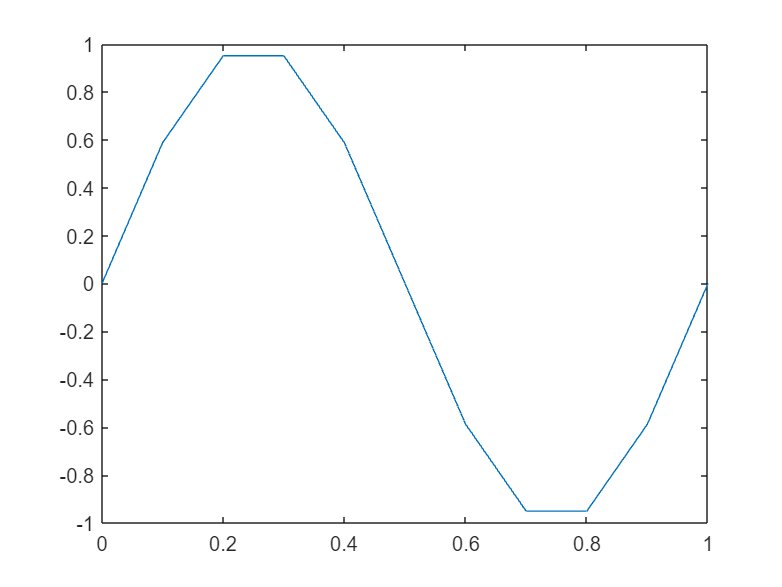

z = zeros(N,1);     %Preallocate the array

for j = 1:N
    z(j) = sin(2 * pi * x(j));
end

plot(x,z)

## Exercise 3

Objective: Plot `x`.x

Details: Using a for loop, create a vector x of 101 equally spaced points between -3 and 7, inclusive. Then create a vector y, such that `y(i) = abs(x(i))*x(i)` using a for loop. Plot the results. 

Your submission should include the code, as in the example, and appropriate comments.

%a=linspace(-3,7,101)
%creating x and y vectors
y=zeros(101,1);

x=zeros(101,1);

%filling y vector with calculations results from the function
for i = 1:101
    x(i)=((7+3)/(101-1))*(i-1)+(-3);

    y(i) = abs(x(i))*x(i);
end
%plotting the function
x

x =    -3.0000
   -2.9000
   -2.8000
   -2.7000
   -2.6000
   -2.5000
   -2.4000
   -2.3000
   -2.2000
   -2.1000


y

y =    -9.0000
   -8.4100
   -7.8400
   -7.2900
   -6.7600
   -6.2500
   -5.7600
   -5.2900
   -4.8400
   -4.4100


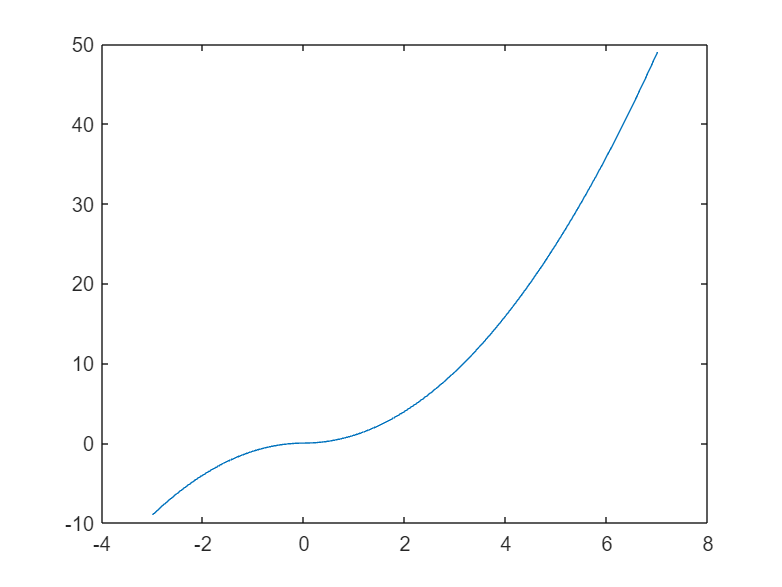

plot(x,y)

## Plotting Two Data Sets at Once

We can also plot the preceding two examples on the same figure with the command `plot(x, y, x, z)`. MATLAB will automatically put a different color on each line. 

h=0.1              %redefine the variables x, y, z

h = 0.1000

x=0:h:1;           %because they might have been
y=x.^2;            %changed in exercise 3
z=sin(2*pi.*x);    %

plot(x,y,x,z)

## Annotating a Figure

It is easy to add a title, axis labels, and a legend to the preceding figure.

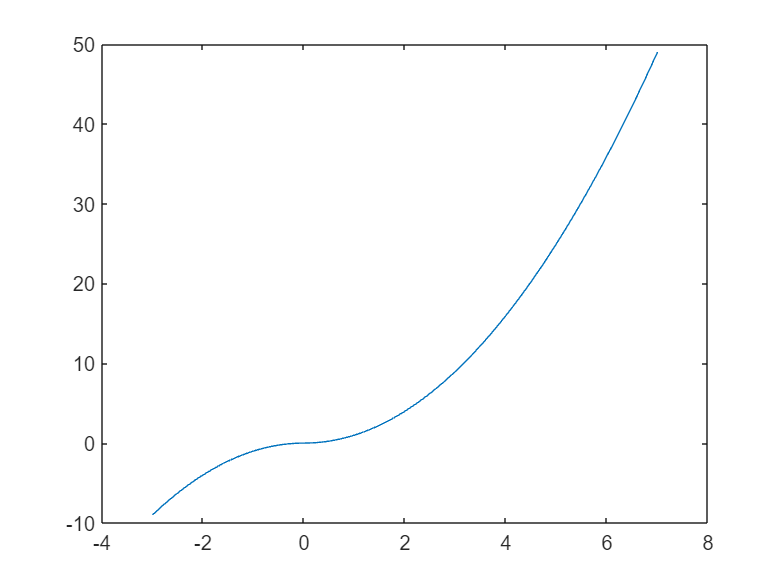

xlabel('x');
ylabel('f(x)');
title('Example plot of two functions plotted on the same figure');
legend('x^2', 'sin(2*pi*x)');

## Using Help Effectively

You can obtain help on any routine at the command line by typing `help commandname`. As you may have noticed in the preceding figure, the legend was not placed in a convenient position. We will now use help to find out how to move the legend to the lower left corner, where it will be less obtrusive.

If you type `help legend` in the command window at the `>>` prompt, you'll see a section:

LEGEND(...,'Location',LOC) adds a legend in the specified location, LOC, with respect to the axes. LOC may be either a 1x4 position vector or one of the following strings:

Thus, if we call `legend` again, with the option  `'Location', 'SouthWest'`, it will move the legend to where we want.

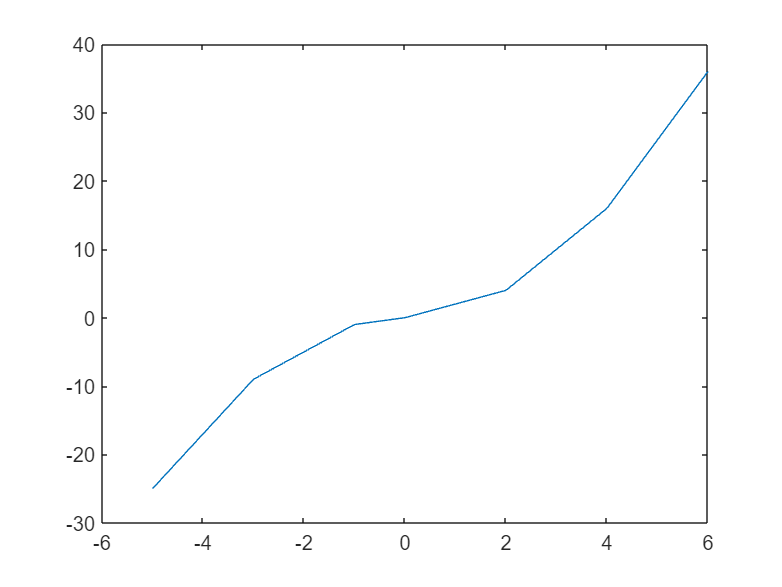

%NOTE: The labels are entered again.
legend('x^2', 'sin(2*pi*x)','Location','SouthWest');

## Vectorization - An Elegant Alternative to Loops

In the previous examples, we used for loops to fill our arrays with the values we wanted. This is very similar to what would be done in C/C++, Java, Fortran, and other languages. 

MATLAB provides a faster way to perform these looped operations, using vectorization, which proccesses the entire vector as a single object. For example, given a vector `x`, we can get the sine of the values in `x` with the command `sin(x)`, which outputs another vector. This works with all built in MATLAB functions. 

Multiplication, division, and exponentiation are handled differently. Instead of using `*`, `/`, and `^`, we must use `.*`, `./`, and `.^` to indicate that we want the operation to be performed on each element. The reason for this change in the symbols is that MATLAB uses the symbols without the period for matrix multiplication, exponentiation, and other actions.

Vectorization yields more concise and less error prone code:

y = x.^2;               %Alternatively, y = x .* x;
z = sin(2 * pi * x);    %NOTE:  Multiplcation by the scalar 2*pi, does not 
                        %       require the .* operator.  Why is that?

plot(x,y,x,z)           %Verify that these are the same results
xlabel('x');
ylabel('f(x)');
title('Example plot of two functions computed by vectorizaiton');
legend('x^2', 'sin(2*pi*x)','Location','SouthWest');

## Speed Comparison

Historically, it was desirable both for clarity and speed to use vecotrized operations in place of loops everywhere possible in MATLAB. Recent versions of MATLAB have reduced the speed advantage through the introduction of a Just in Time (JIT) compiler, parallel for loops, and other tools.

However, we can still demonstrate the speed advantage, and the benefit to clarity is already evident.

Timing is done with the `tic`, `toc` commands, which enclose the region we want to benchmark. The first output is the time for the construction done by looping, the second output is the time for construction done with vectorization.

clear y;    %Clear the y array
tic;        %Begin timing the construciton and filling of the array

y = zeros(N,1);

for j = 1:N
    y(j) = x(j)^2;
end

toc;

Elapsed time is 0.003027 seconds.



clear y;    %Clear the y array
tic;
y = x.^2;
toc;

Elapsed time is 0.001769 seconds.


## Exercise 4

Objective: Compare the speedup from vectorization for a larger vector.

Details: Create a vector `x` of 5000001 equally space points between -2 and 3, inclusive, using a for loop. Then time the construction of vector `y`, whose values are arctan of x, by a for loop and by vectorization. Be sure to clear  `y` between the two runs. (Hint: use the help file to find the command for arctan!)

Your submission should include the code, as in the example, with appropriate comments.

%make the vector x 
x=zeros(5000001,1);
for i=1:5000001
    x(i)=((3+2)/5000000)*i-2;
end
%time for construction of vector y using vectorization
tic;
y=atan(x);

y =    -1.1071
   -1.1071
   -1.1071
   -1.1071
   -1.1071
   -1.1071
   -1.1071
   -1.1071
   -1.1071
   -1.1071


toc;

Elapsed time is 0.071156 seconds.


%time for construction of vector y using for loop
tic;
y=zeros(5000001,1);
for i=1: 5000001
    y(i)=atan(x(i));
end

toc;

Elapsed time is 0.090721 seconds.


%plotting y against x
x

x =    -2.0000
   -2.0000
   -2.0000
   -2.0000
   -2.0000
   -2.0000
   -2.0000
   -2.0000
   -2.0000
   -2.0000


y

y =    -1.1071
   -1.1071
   -1.1071
   -1.1071
   -1.1071
   -1.1071
   -1.1071
   -1.1071
   -1.1071
   -1.1071


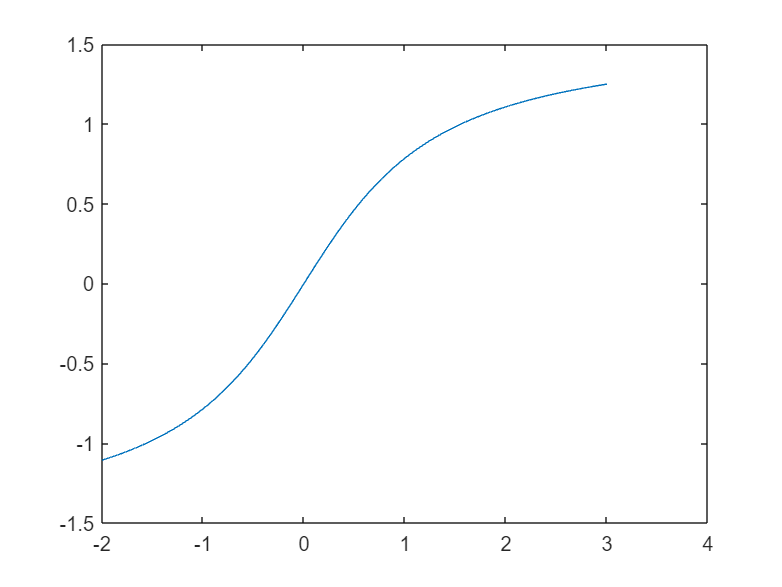

plot(x,y)

%z=linspace(-2,3,5000001)

## Further Avoiding Loops with linspace

In the preceding examples, we will focus on the vector `x`, which was constructed with a `for` loop. MATLAB includes a routine for creating a vector of a given number, `N`, of equally spaced points between two values, `a` and `b`:

`x = linspace(a, b, N);`

No preallocation is neccessary. The argument `N` is optional. If it is omitted MATLAB uses 100 points by default.

We will now use linspace to plot the functions y = x - x^3 and y = exp(x) in the range [-2, 4] with 200 points.

clear all;                  %Clears all variables

x = linspace(-2,4, 200);    %Create the array

y = x - x.^3;
z = exp(x);

plot(x,y,x,z)           %Verify that these are the same results
xlabel('x');
ylabel('f(x)');
title('Example plot of two functions generated by vectorizaiton');
legend('x-x^3', 'exp(x)','Location','SouthWest');

## Exercise 5

Objective: Solve an ODE and plot three particular solutions.

Details: Manually find the general solution of the ODE:

dy/dt + (2*t)*y = 1/exp(t^2)

and the particular solutions for initial conditions y(1) = -1, y(1) = 0, and y(1) = 1. Plot these three particular solutions on the same axes lettting the independent variable range from 1 to 5. 

Once you have the three particular solutions you will need to:

Your submission should include, in the description section, the general solution of the ODE and the three particular solutions. It should also have the appropriately commented code.

 

%dy/dt + (2*t)*y = 1/exp(t^2) 
% where 2t = P(x) and 1/exp(t^2) = f(x)
% I(t) = exp(int 2t dt) = exp (t^2)
% to find the general solution y= 1/exp(t^2)  *  int(I* (1/exp(t^2) dt + C)
% crossing out exp(t^2)
% the general solution is y=(t + C)/exp(t^2)

%for y(1) = -1   vector name A
% C = -e-1
% particular solution y = (t-e-1)/exp(t^2)

%for y(1) = 0    vector name B
% C = -1
% particular solution y = (t-1)/exp(t^2)

%for y(1) = 1    vector name C
% C = e-1
% particular solution y = (t+e-1)/exp(t^2)

t=linspace(1,5,100); %make an equally spaced t

t =     1.0000    1.0404    1.0808    1.1212    1.1616    1.2020    1.2424    1.2828    1.3232    1.3636    1.4040    1.4444    1.4848    1.5253    1.5657    1.6061    1.6465    1.6869    1.7273    1.7677    1.8081    1.8485    1.8889    1.9293    1.9697    2.0101    2.0505    2.0909    2.1313    2.1717    2.2121    2.2525    2.2929    2.3333    2.3737    2.4141    2.4545    2.4949    2.5354    2.5758    2.6162    2.6566    2.6970    2.7374    2.7778    2.8182    2.8586    2.8990    2.9394    2.9798



%solve for each particular solution
A=(t-exp(1)-1)./exp(t.^2)

A =    -1.0000   -0.9072   -0.8201   -0.7388   -0.6632   -0.5933   -0.5289   -0.4698   -0.4158   -0.3667   -0.3223   -0.2823   -0.2463   -0.2141   -0.1855   -0.1601   -0.1377   -0.1180   -0.1008   -0.0857   -0.0727   -0.0614   -0.0516   -0.0433   -0.0361   -0.0300   -0.0249   -0.0205   -0.0169   -0.0138   -0.0113   -0.0092   -0.0074   -0.0060   -0.0048   -0.0038   -0.0031   -0.0024   -0.0019   -0.0015   -0.0012   -0.0009   -0.0007   -0.0005   -0.0004   -0.0003   -0.0002   -0.0002   -0.0001   -0.0001


B=(t-1)./exp(t.^2)

B =          0    0.0137    0.0251    0.0345    0.0419    0.0476    0.0518    0.0546    0.0561    0.0566    0.0563    0.0552    0.0535    0.0513    0.0488    0.0459    0.0430    0.0399    0.0368    0.0337    0.0307    0.0278    0.0251    0.0225    0.0200    0.0178    0.0157    0.0138    0.0120    0.0105    0.0091    0.0078    0.0067    0.0058    0.0049    0.0042    0.0035    0.0030    0.0025    0.0021    0.0017    0.0014    0.0012    0.0010    0.0008    0.0006    0.0005    0.0004    0.0003    0.0003


C=(t+exp(1)-1)./exp(t.^2)

C =     1.0000    0.9346    0.8704    0.8078    0.7471    0.6886    0.6324    0.5789    0.5280    0.4800    0.4349    0.3926    0.3532    0.3167    0.2830    0.2520    0.2237    0.1979    0.1744    0.1532    0.1341    0.1170    0.1018    0.0882    0.0762    0.0656    0.0563    0.0481    0.0410    0.0348    0.0295    0.0248    0.0209    0.0175    0.0146    0.0122    0.0101    0.0083    0.0069    0.0056    0.0046    0.0038    0.0031    0.0025    0.0020    0.0016    0.0013    0.0010    0.0008    0.0007


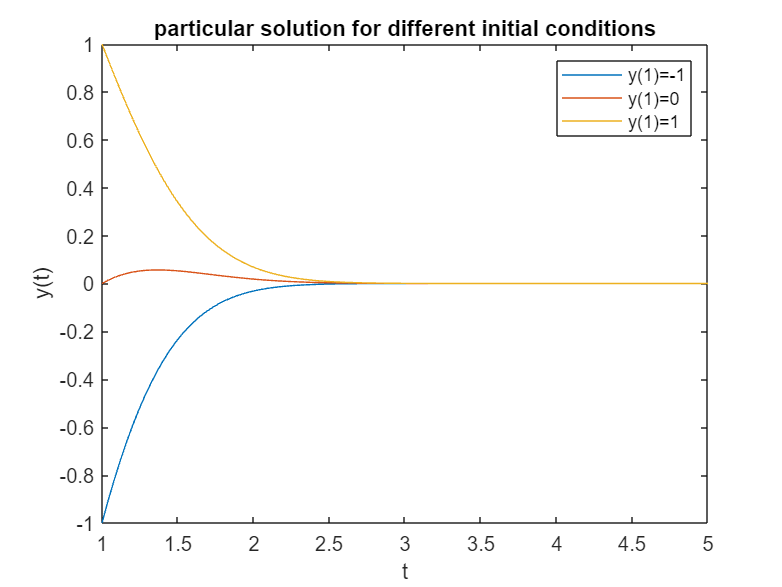

%plot graph in the same axes
plot(t,A,t,B,t,C)

xlabel('t');
ylabel('y(t)');
title('particular solution for different initial conditions');
legend('y(1)=-1', 'y(1)=0','y(1)=1');

## More Plotting Examples - Line Style

There are many plotting options available, including color, line style, and marker style. Some options can be found from the `help plot` command. This is done by incuding a command after each line.

In the first we example we will vary the line style.

x = linspace(-5,5);

%Plot three functions with different line styles.  NOTE: the
%function can be put directly in the plot argument.
plot(x, sin(x),'--', x, cos(x),'-.', x, exp(-x.^2),':');   
legend('sin', 'cos', 'exp(-x^2)');

## More Plotting Examples - Line Color

We can also control the color, mixing it with line style.

%Plot two functions, first in green and then in red.
x = linspace(-1,1);
plot(x, x.^3 .* sin(x), 'g', x, -x .* exp(x), 'r-');
legend('x^3 * sin(x)', '-x * exp(x)');

## More Plotting Examples - Markers

Markers can be used at the individual points, with and without a line joining the points.

x = linspace(-4,4, 20);
plot(x, sin(x), 'x-', x, (x.^2)./(1+x.^2), '.');
legend('sin(x)', 'x^2/(1+x^2)');

## Inline functions of one variable

Suppose we wish to construct the function:

`f(x) = x * sin(x)`

In a way that MATLAB can understand and manipulate. This will let us compute values of `f(x)`, plot it, and create other functions from it.

This can be accomplished by defining an inline function of one variable, with the command:

function name = @(argument name) mathematical expression;

For this example, the function name is `f`, the argument name is `x`, and the mathematical expression is `x * sin(x)`.

Consider the following examples, and take note of:

1. The use of vectorization in the definitions, 2. The different ways that the output can be displayed, 3. The different variable names.

f = @(x) x .* sin(x);

x = 1;
fprintf(' f(%g) = %g\n', x, f(x));

 f(1) = 0.841471


fprintf(' f(%g) = %g\n', 1, f(1));

 f(1) = 0.841471


disp(f(1));

    0.8415



f(1)

ans = 0.8415

x = 2;
fprintf(' f(%g) = %g\n', 2, f(2));

 f(2) = 1.81859


fprintf(' f(%g) = %g\n', 2, f(2));

 f(2) = 1.81859


disp(f(2));

    1.8186



f(2)

ans = 1.8186


disp(f([1,2]))

    0.8415    1.8186




g = @(t) t.^2 - t +1;
g(1)

ans = 1

g(2)

ans = 3

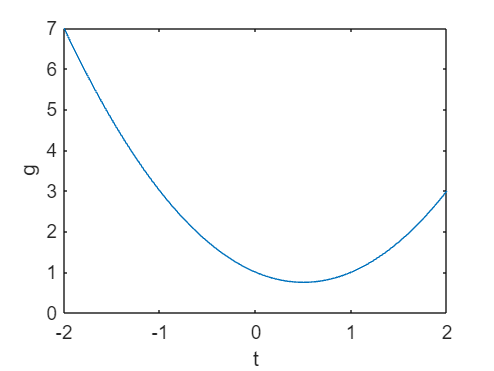


% Construct an array of 100 grid points from -2 to 2, and plot g(t).
t = linspace(-2,2);
plot(t, g(t));
% Label axes
xlabel('t');
ylabel('g');

## Exercise 6

Objective: Write and use an inline function of one variable.

Details: Define the inline function for

`f(x) = (x^3 - abs(x)) * ln(x^2+1)`

Use this function to compute `f(0)`, `f(1)`, and `f(-1)` and plot the function with 100 grid points from -5 to 5. Make sure to use vectorization in your definition, and label your axes.

Your submission should show the definition of the function, and the computation of these values.

%creating inline function f from given function 
f =@(x) (x.^3 - abs(x)) .* log(x.^2+1)

f = function_handle with value:
    @(x)(x.^3-abs(x)).*log(x.^2+1)



%solving for f(0), f(1), and f(-1)
f(0)

ans = 0

f(1)

ans = 0

f(-1)

ans = -1.3863


%creating evenly spaced vector for x axis
x=linspace(-5,5,100);

x =    -5.0000   -4.8990   -4.7980   -4.6970   -4.5960   -4.4949   -4.3939   -4.2929   -4.1919   -4.0909   -3.9899   -3.8889   -3.7879   -3.6869   -3.5859   -3.4848   -3.3838   -3.2828   -3.1818   -3.0808   -2.9798   -2.8788   -2.7778   -2.6768   -2.5758   -2.4747   -2.3737   -2.2727   -2.1717   -2.0707   -1.9697   -1.8687   -1.7677   -1.6667   -1.5657   -1.4646   -1.3636   -1.2626   -1.1616   -1.0606   -0.9596   -0.8586   -0.7576   -0.6566   -0.5556   -0.4545   -0.3535   -0.2525   -0.1515   -0.0505


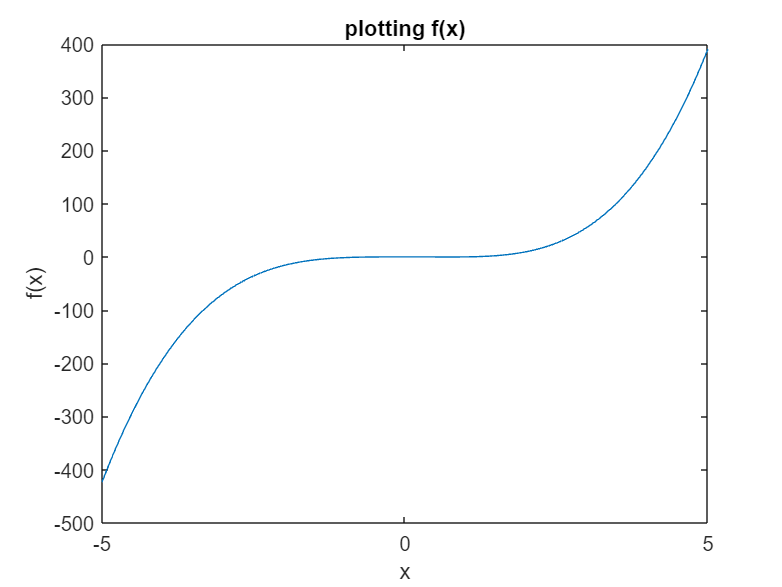


%plotting and labeling
plot(x,f(x))
xlabel('x');
ylabel('f(x)');
title('plotting f(x)');

## Inline functions of two variables

Suppose we wish to solve the equation 

`x = y^3 + y`

for `y` as a function of `x`. If we do this by root finding, then, given a value of `x0`, we need to find the root of the function

`g(y) = f(x0,y) = y^3 + y - x0`

We will accomplish this using inline functions.

Inline functions of two variables are defined as:

func = @(x,y) f(x,y);

where func is the name you wish to assign your function, and `f(x,y)` is the relevant expression.

Some examples of defining and using inline functions of two variables are given below. 

f = @(x,y) y.^3 + y - x;
x = 0; y = 0;
fprintf(' f(x = %g, y = %g) = %g\n', x, y, f(x, y));

 f(x = 0, y = 0) = 0


x = 0; y = 1;
fprintf(' f(x = %g, y = %g) = %g\n', x, y, f(x, y));

 f(x = 0, y = 1) = 2


disp(f(x,y))

     2



f(0,1)

ans = 2


h = @(t,u) t.^2  + sin(u);
h(1, pi/2)

ans = 2

h(2, 2)

ans = 4.9093

## Exercise 7

Objective: Write and use an inline function of two variables.

Details: Define the inline function for

`f(x,y) = y + y^3 - cos x + x^2 - x^4`

Note that `f(x,y) = c` is the implicit solution to 

`dy/dx = (4x^3 - 2x - sin x)/(1+3y^2)`.

See Examples 1-3 of section 2.1 in Brannan and Boyce for similar examples.

Use this function to compute `f(0, 0)`, `f(pi/2,1)`, and `f(-1,-1)`. Make sure to use vectorization in your definition.

Your submission should show the definition of the function, and the computation of these values.

%definition of inline function for given function
f=@(x,y) y + y.^3 - cos(x) + x.^2 - x.^4

f = function_handle with value:
    @(x,y)y+y.^3-cos(x)+x.^2-x.^4



%computation of f(0, 0), f(pi/2,1), and f(-1,-1)
f(0, 0)

ans = -1

f(pi/2,1)

ans = -1.6207

f(-1,-1)

ans = -2.5403

## Numerically solving an implicit equation

Given `x0`, we will now solve the equation

`f(x0, y) = y^3 + y - x0 = 0`

for y. This will be accomplished using fzero, which employs a more advanced form of Newton's method. 

The minimal arguments needed for using fzero are:

fzero(function_handle, guess)

function_handle is an abstract data structure which directs MATLAB towards a function of a single variable that it will try to zero.

We need to tell MATLAB that it is trying to solve for the `y` argument. This is done by creating an inline function of one variable from the existing function, i.e.

g = @(y) f(x0, y)

And then having fzero try to solve

`g(y) = 0`

You can either define the new inline function and use it:

g = @(y) f(x0, y); 

y = fzero(g, guess);

or you can put the inline function argument directly in the function handle argument:

y = fzero(@(y) f(x0,y), guess);

The guess is an initial guess for what we anticipate y to be. Finding a good initial guess may require some experimentation. For this example, the guess may be quite poor, and the algorithm will still converge. For others, more care must be taken.

Note the various ways of constructing the inline function of one variable, and the different guesses.

f = @(x,y) y.^3 + y - x;

x0 = 1

x0 = 1

guess = 1

guess = 1

g = @(y) f(x0, y)

g = function_handle with value:
    @(y)f(x0,y)


y = fzero(g, guess)

y = 0.6823

fprintf(' y(%g) = %g\n', x0, y)

 y(1) = 0.682328



guess = 50

guess = 50

y = fzero(g, guess)

y = 0.6823

fprintf(' y(%g) = %g\n', x0, y)

 y(1) = 0.682328



x = 2

x = 2

g = @(y) f(x, y)

g = function_handle with value:
    @(y)f(x,y)


y = fzero(g, 2)

y = 1

fprintf(' y(%g) = %g\n', x, y)

 y(2) = 1



guess = 2

guess = 2

y = fzero(@(y) f(2, y), guess)

y = 1

fprintf(' y(%g) = %g\n', 2, y)

 y(2) = 1


## Exercise 8

Objective: Use fzero to solve an equation `f(x,y)=0` for y at different values of x.

Details: Consider the function

`f(x,y) = y + y^3 - cos x + x^2 - x^4`

Define the appropriate inline function and compute the single solution at `x = 0` and the two positive solutions at `y = 1/2`. 

You will need to experiment with different guesses to get these three solutions.

Your submission should show the definition of the function, and the computation of these three roots.

%defining inline function f from given function
f =@(x,y) y + y^3 - cos(x) + x^2 - x^4

f = function_handle with value:
    @(x,y)y+y^3-cos(x)+x^2-x^4


%solving for y for x=0 using fzero
x=0;

x = 0

z1=@(y) f(x,y);

z1 = function_handle with value:
    @(y)f(x,y)


fprintf(' y(%g) = %g\n', x, fzero(z1, x))

 y(0) = 0.682328



%solving for x for y=1/2 using fzero
y=1/2;

y = 0.5000

z2=@(x) f(x,y);

z2 = function_handle with value:
    @(x)f(x,y)


fprintf(' y(%g) = %g\n', y, fzero(z2, 10))

 y(0.5) = 1.05844


fprintf(' y(%g) = %g\n', y, fzero(z2, 0.2))

 y(0.5) = 0.567406


%guesses are chosen because tested results gives two positive results

## Plotting the solution

Now we are ready to plot y as a function of x. We will construct an array of x values, solve for y at each value of x, and then plot the results. This will be accomplished with a for loop.

f = @(x,y) y.^3 + y - x;

% 50 points equally spaced from -5 to 2, inclusive
xvals = linspace(-5, 2, 50); 

% Preallocate storage space for the solutions
yvals = zeros(size(xvals));      

% Loop through all the values
for j = 1:length(xvals)
   
   yvals(j) = fzero(@(y) f(xvals(j), y), 0);
   
end

% Plot the results

plot(xvals, yvals);
xlabel('x');
ylabel('y');

## Exercise 9

Objective: Plot a portion of an implicit equation.

Details: Plot the portion of the solution to

`f(x,y) = y + y^3 - cos x + x^2 - x^4`

passing through the point `(0,0)` for x from -2 to 2. Use 100 grid points.

You will need to be careful with the initial guess you use in solving the equation.

Your submission should show the definition of the function, the construction of the arrays, the for loop, and the resultant figure.

Label your axes.

%the given function does not pass through (0,0), to make it pass through
%origin, we have to shift the function by substituting function f(x,y) with
%(0,0) which results in -1. Thus, we have to add 1 to the function to shift
%the function by 1 downwards

%make inline function f from given function
f =@(x,y) y + y^3 - cos(x)+ x^2 - x^4+1;

f = function_handle with value:
    @(x,y)y+y^3-cos(x)+x^2-x^4+1



%make an evenly spaced vector x
x=linspace(-2,2,100);

x =    -2.0000   -1.9596   -1.9192   -1.8788   -1.8384   -1.7980   -1.7576   -1.7172   -1.6768   -1.6364   -1.5960   -1.5556   -1.5152   -1.4747   -1.4343   -1.3939   -1.3535   -1.3131   -1.2727   -1.2323   -1.1919   -1.1515   -1.1111   -1.0707   -1.0303   -0.9899   -0.9495   -0.9091   -0.8687   -0.8283   -0.7879   -0.7475   -0.7071   -0.6667   -0.6263   -0.5859   -0.5455   -0.5051   -0.4646   -0.4242   -0.3838   -0.3434   -0.3030   -0.2626   -0.2222   -0.1818   -0.1414   -0.1010   -0.0606   -0.0202


y=zeros(size(x));

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


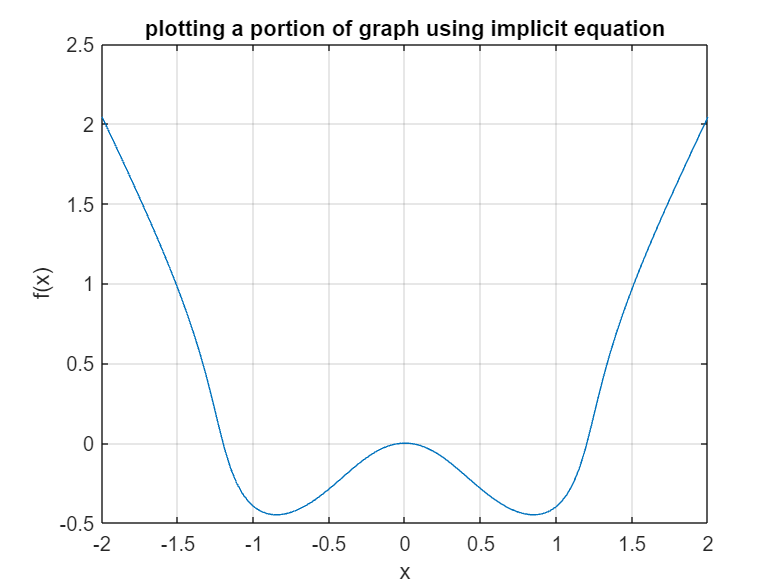


%solve for y(x) for each point in x
for i=1:100
    z=@(y) f(x(i), y);
    y(i) = fzero(z,0);
end

%plotting and labeling
plot(x,y)
xlabel('x');
ylabel('f(x)');
title('plotting a portion of graph using implicit equation');
grid on

## Exercise 10

Objective: Solve a differential equation and plot a portion of it.

Details: Find the general implicit solution of the differential equation

`dy/dx = (-cos x + 3x^2) y`

Plot the particular solution passing through y(0) = 1 using 100 grid points for x in [-1.5, 1.25].

Be careful on your choice of guess. You will be penalized if MATLAB shows an error.

Your submission should show the general and particular solutions, in implicit form, in the comments, the definition of the appropriate inline functions, arrays, the for loop, and the figure.

Label your axes.

%solving for general implicit solution
%f=@(x,y) (-cos(x)+3*x^2)*y
% y =exp (-sinx+x^3) +C 
clear all
%solving for particular solution with y(0)=1
% we get 1=exp(0) + C which means C=0
%so the particular solution is y =exp (-sinx+x^3)
%now we make the inline function
f=@(x,y) y-exp(-sin(x)+x.^3);

f = function_handle with value:
    @(x,y)y-exp(-sin(x)+x.^3)



%making evenly spaced x vector
x=linspace(-1.5,1.25,100);

x =    -1.5000   -1.4722   -1.4444   -1.4167   -1.3889   -1.3611   -1.3333   -1.3056   -1.2778   -1.2500   -1.2222   -1.1944   -1.1667   -1.1389   -1.1111   -1.0833   -1.0556   -1.0278   -1.0000   -0.9722   -0.9444   -0.9167   -0.8889   -0.8611   -0.8333   -0.8056   -0.7778   -0.7500   -0.7222   -0.6944   -0.6667   -0.6389   -0.6111   -0.5833   -0.5556   -0.5278   -0.5000   -0.4722   -0.4444   -0.4167   -0.3889   -0.3611   -0.3333   -0.3056   -0.2778   -0.2500   -0.2222   -0.1944   -0.1667   -0.1389


y=zeros(100);

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

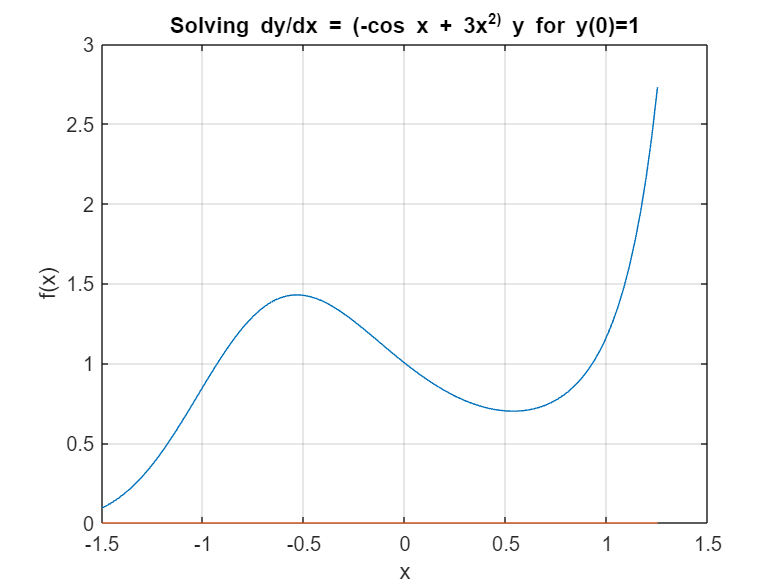


%then solving for y(x) for each point in x
for i=1:100
    y(i)=fzero(@(y) f(x(i),y),0);
end

%plotting and labeling the graph
plot(x,y)
xlabel('x');
ylabel('f(x)');
title('Solving dy/dx = (-cos x + 3x^2) y for y(0)=1');
grid on

## Install iode

Objective: install iode

Details: visit [https://faculty.math.illinois.edu/iode/](https://faculty.math.illinois.edu/iode/) and follow the instructions there to download and install iode.

## Exercise 11

Objective: use iode a plot the direction field of a differential equation

Details: After starting iode, click the "direction fields" buttom from the main menu. The default is the direction field for

`dy/dx = sin(y-x)`

Click any point in the x-y plane to see a (numerically computed) solution to the differential equation passing through that point.

Starting from the "Equation" menu, plot the direction field of 

`dy/dx = xy^2`

Describe, in words, the behaviour of the solutions. What happens as x approaches infinity? Explain why solutions are symmetric about the y-axis, i.e. `y(x)=y(-x)` for any solution.

%{
as x approaches infinity and y also approaches infinity, the graph has an increased slope
and (similar to the behaviour of exp(x) as it approaches infinity). The
graph is symmetrical about the x axis, making u shaped curve on the
positive y side of the graph.
    
as y approaches negative infinity, the slope of the lines also increased.
all the lines creates an upside down bell-like curve with the curve being
more defined as y approaches infinity. 

the graph is symmetrical about the y-axis, because the function dy/dx=x*y^2
has a general solution y=c/exp(-(x^2)/2) which means that y(x)=y(-x)
because the quadratic of x or -x will always result in x^2
%}


## Exercise 12

Objective: study the long-run behaviour of a differential equation from its direction field

Details: Using iode, plot the direction field of 

`dy/dx = y^4 - y^3 - 3*y^2 + y + 2`

By clicking on various initial conditions `y(0) = y_0` (iode plots the solution), determine the long-run behaviour of solutions as a function of `y_0`. In other words, list the constant solutions that are approached as x goes to infinity and how `y_0` determines which constant solution is approached.

If your numerically computed solutions ever appear to cross then change the solution method from Euler to the, much better, Runge-Kutta method. Think about why solutions are not permitted to cross. If they do then this indicates a problem with the numerical solver.

%{
 Along the graph, the lines approaches 3 different horizontal solutions.
 These are 
 y=-1, y=1, y=2

As x approaches infinity, when y is [-2, -1], the line will come from
negative y infinity close to the initial x to positive x infinity, while it
approaches y= -1 solution
 However, when y becomes smaller than -2, the curves starts to stop
 approaching the -1 solution, instead it starts approching the upper
 solution (1, and 2), and as y approaches negative infinity, the curves
 stops approaching the horizontal solution at all and starts moving
 towards infinity.

initial conditions y=[-1, 1] will always have an s like curve, where the
upper curve approaches y=1 and the lower part of the curve approaches y=-1

Similarly, bounds y=[1,2] follows the same behaviour, but with mirrored
shape (curving direction) where it approaches upper solution of y=2 and
lower solution of y=1. 

Lastly, when y>2, the curve behaves similarly to y<-1 where as y initial
get larger, it starts approaching lower and lower solutions

y_0 decides which solution must be approached as x approaches infinity or
negative infinity

The solutions are not permitted to cross because when an ODE has a particular
solution, it will only have one unique solution. If they do cross, then on
of the solution must be wrong and it indicates that there is a problem with
the numerical solver.
%}

## Exercise 13 (NOT TO BE HANDED IN)

Objective: Solve a differential equation and plot the largest interval of existence for this solution.

Details: Find the particular implicit solution of the differential equation

`dy/dx = -x/y, y(0) = -2`

Determine the largest interval of validity and plot the solution with 50 grid points in this interval.

In the comments before your code, explain why fzero has an error.

Your submission should show the particular solution, in implicit form, in the comments, the definition of the appropriate inline functions, arrays, loops, and the figure. 

Label your axes.

## Exercise 14 (NOT TO BE HANDED IN)

Objective: Solve a differential equation and plot the solution on the specified interval

Details: Find the particular implicit solution of the differential equation

`du/dt = -(u^4 - 1), u(0) = .1`

and plot it for `t` from 0 to 1.

Determine a good starting guess that works throughout the interval and plot the solution with 50 grid points in this interval.

Your submission should show the particular solution, in implicit form, in the comments, the definition of the appropriate inline functions, arrays, loops, and the figure.

Label your axes.

%}